
filename = "output_adxl_data_y1.csv"

filename = "output_adxl_data_y1.csv"


data = readmatrix(filename);

t = data(:,1);
x = data(:,2);
y = data(:,3);
z = data(:,4);

data = y;

%[b,a] = butter(4, fc/(Fs/2));   % 4th-order Butterworth LPF
%data = filter(b, a, data);
%data = movmean(data, 5);
%data = data - mean(data);


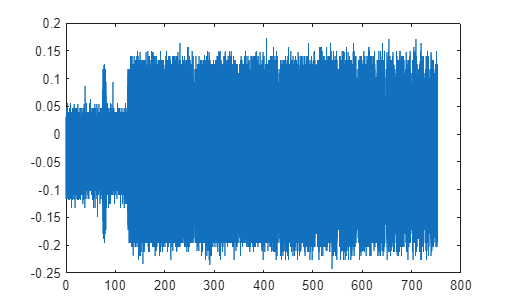

figure;
plot(t, data);

ranges_y1 = [132.92, 256.525;
    266.783, 345.502;
    355.025, 426.775;
    435.834, 503.717;
    511.12, 548.879;
    554.327, 587.174;
    592.766, 625.829;
    629.993, 645.44;
    649.65, 664.995;
    669.226, 684.433;
    688.481, 698.123;
    701.958, 711.287;
    715.399, 724.469;
    728.559, 735.022;
    739.002, 744.839;
    749.025, 752.343];

ranges_y2 = [21.8069, 144.946;
    158.421, 233.904;
    243.329, 314.113;
    322.335, 389.921;
    396.551, 435.686;
    442.35, 474.055;
    478.555, 510.962;
    515.374, 530.905;
    535.155, 550.325;
    554.391, 569.516;
    573.878, 582.954;
    587.12, 596.16;
    600.527, 609.715;
    613.78, 620.136;
    624.129, 630.567;
    634.444, 640.847;
    645.099, 649.539;
    653.636, 658.267;
    662.456, 666.7;
    671.049, 674.581];

ranges_y3 = [28.9264, 144.439;
    155.117, 233.006;
    242.094, 313.833;
    321.618, 389.722;
    396.816, 434.949;
    440.696, 474.157; 
    479.239, 511.022;
    515.853, 530.982;
    535.769, 550.618;
    555.291, 569.982;
    573.885, 583.719;
    587.946, 596.905;
    600.99, 610.564;
    614.206, 620.989;
    625.209, 631.223;
    635.278, 641.426;
    645.888, 650.201;
    655.138, 659.507;
    663.664, 668.297;
    672.579, 676.21];

ranges_x1 = [33.39, 148.68;
    168.7, 243.47;
    255.39, 324.31;
    336.3, 399.89;
    410.63, 443.32;
    453.29, 483.57;
    492.77, 520.27;
    526.42, 540.95;
    545.94, 560.71;
    565.775, 579.9;
    584.245, 593.375;
    599.3, 607.015;
    611.35, 620.28;
    624.75, 630.55;
    634.64, 641.001;
    644.93, 651.45;
    656.074, 660.501;
    664.68, 669.405;
    673.668, 678.008;
    681.934, 685.975];

ranges_x2 = [0.09678, 18.2656;
    24.1339, 57.0081;
    62.6426, 94.5849;
    101.546, 115.083;
    119.781, 134.567;
    139.479, 154.184;
    159.148, 167.783;
    172.363, 181.495;
    185.823, 194.703;
    198.871, 204.73;
    208.945, 215.042;
    219.281, 225.115;
    229.7, 233.903;
    239.088, 243.715;
    248.097, 252.42;
    256.564, 259.884];

ranges_x3 = [137.022, 249.659;
    263.008, 340.591;
    353.757, 420.136;
    431.169, 494.803;
    502.219, 538.581;
    544.561, 577.427;
    583.275, 614.464;
    620.558, 635.708;
    640.825, 654.886;
    661.266, 675.089;
    679.984, 688.674;
    693.324, 702.094;
    706.331, 714.863;
    720.318, 725.952;
    729.914, 736.176;
    740.45, 746.461;
    750.794, 755.427;
    759.783, 764.54;
    768.546, 773.119;
    777.006, 780.82];



ranges = ranges_x1;

Fs = 1/(t(2)-t(1));   % sampling frequency

results = [];

for k = 1:size(ranges,1)

    t_start = ranges(k,1);
    t_end   = ranges(k,2);

    % indices of this segment
    idx = (t >= t_start) & (t <= t_end);

    x = data(idx);

    X = fft(x);
    N = length(x);

    X = X / N;
    
    X = X(1:floor(N/2));
    X(1) = 0;
    
    %[~, i] = max(abs(X(2:end)));
    [~, i] = max(abs(X));
    e = max(i-10,1):min(i+10,length(X));
    disp(i);

    X_p = abs(X).^2; % vykonove spektrum
    X_p = X_p * 2; % kompenzace jednostranneho spektra
    
    P = sum(X_p(e));
    
    A = sqrt(2*P);

    % === lepší odhad frekvence (parabolická interpolace) ===
    if (i > 1) && (i < length(X))
        alpha = X(i-1);
        beta  = X(i);
        gamma = X(i+1);

        p = 0.5 * (alpha - gamma) / (alpha - 2*beta + gamma);
        f_main = (i-1 + p) * Fs / N;
    else
        f_main = f(i);
    end

    % store
    results = [results; A, f_main];
end

   229

   186

   216

   253

   163

   190

   219

   145

   184

   225

   182

   192

   280

   231

   316

   408

   352

   469

   539

   642




figure;
scatter(results(:, 2), results(:, 1)/0.1, "+");

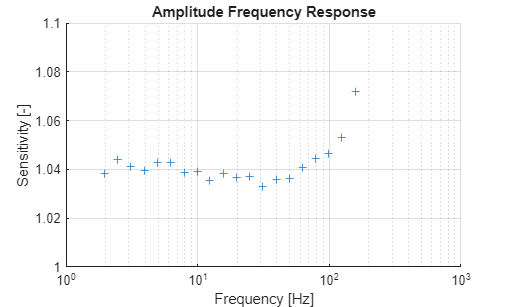

title("Amplitude Frequency Response");
xlabel("Frequency [Hz]");
ylabel("Sensitivity [-]");
xscale("log");
ylim([1 1.1]);
xlim([1 1000]);
grid on
hold on



% --- save to CSV ---
%writematrix(results, 'output_bno_y3_bez_filtru.csv');


## Wavelet transform


Fs = 1/(t(2)-t(1)); % sampling frequency

%% ===== COMPUTE CWT =====
% 'amor' = Morlet wavelet (nejlepší pro vibrace)
[cfs, F] = cwt(x, Fs, 'amor');

% převod na dB
C_dB = 20*log10(abs(cfs) + 1e-12);


## Plot WT


set(0,'DefaultFigureVisible','on')

%% ===== PLOT =====
figure;
imagesc(t, F, C_dB);
axis xy;

set(gca, 'YScale', 'log');   % log frekvence

xlabel('Time [s]');
ylabel('Frequency [Hz]');

colormap(jet);
cb = colorbar;
cb.Label.String = 'Amplitude [dB re 1g]';

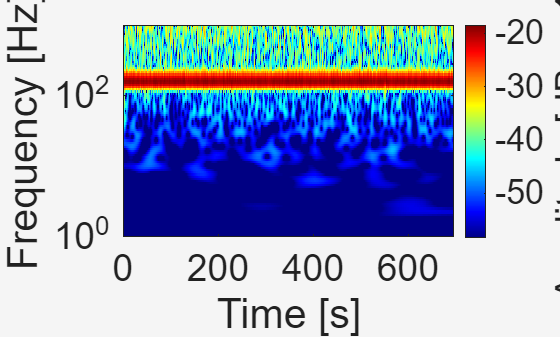

cb.Label.FontSize = 28;

% dynamický rozsah
clim([max(C_dB(:))-40, max(C_dB(:))]);

% omezení frekvenčního rozsahu (upravit dle potřeby)
ylim([1 1000]);

set(gca, 'FontSize', 28);

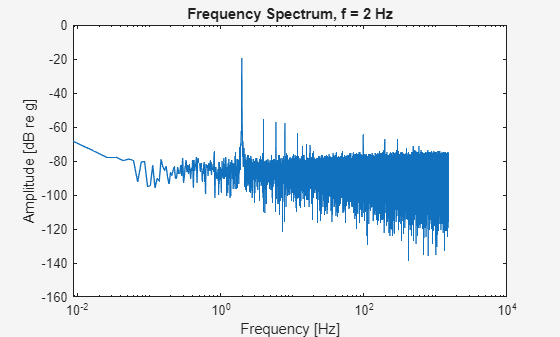

idx = (t >= ranges(1, 1)) & (t <= ranges(1, 2));
data_fft = data(idx);

spectrum = abs(fft(data_fft)) / length(data_fft);
spectrum(2:end-1) = 2*spectrum(2:end-1); 
spectrum = spectrum(1:round(length(spectrum)/2));

spectrum = 20*log10(spectrum);

f = linspace(0, Fs/2, length(spectrum));
figure;
plot(f, spectrum);
title("Frequency Spectrum, f = 2 Hz")
xlabel('Frequency [Hz]');
ylabel('Amplitude [dB re g]');
xscale('log');
ylim([-160, 0]);

hold on